px = [-10 -5 0 5 10];
py = [0.0001 -0.1 0 0.1 -0.0001];
stopien=5

stopien = 5

W = polyfit(px, py, stopien)

W =    -0.0000    0.0000    0.0011   -0.0000         0    0.0000


fx=@(x)(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x

fx = function_handle with value:
    @(x)(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x


[x1,y1,z1] = ekspansion_method(-8, 0.1, fx, 1.5 ,10000)

x1 = -5.4371

y1 = -2.2335

z1 = 10

[x2,y2,z2] = contraction_method(x1, y1, fx, 0.99 ,10000)

x2 = -4.5795

y2 = -2.2335

z2 = 33

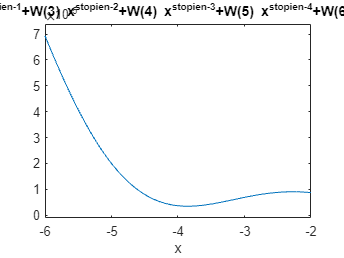


ezplot(fx,[-6,-2])